# Próbkowanie sygnałów ciągłych

### Mateusz Wójcik, 21.11.2024

Próbkowanie to zamiana sygnału ciągłego, np. dźwięku lub obrazu, w sygnał dyskretny, który można zapisać w formie cyfrowej. Kluczowym aspektem próbkowania jest dobór odpowiedniej częstotliwości próbkowania, która musi być wystarczająco wysoka, aby dokładnie odtworzyć sygnał. Jeśli częstotliwość próbkowania jest zbyt niska, dochodzi do zjawiska aliasingu.

**Aliasing** to błąd w odtwarzaniu sygnału, polegający na nakładaniu się wyższych częstotliwości na niższe, co prowadzi do zniekształceń. Sprawia to, że odtworzony sygnał różni się od oryginalnego. Zjawisko to pojawia się, gdy sygnał zawiera składowe o wyższej częstotliwości niż połowa częstotliwości próbkowania (zgodnie z twierdzeniem Nyquista-Shannona).

W życiu codziennym można spotkać wiele przykładów aliasingu, np. zjawisko zmiany kierunku kręcenia się koła na filmie, zniekształcenia dźwięku w mikrofonie, ruch wentylatorów obserwowanych pod światłem o danej częstotliwości migania, jeśli częstotliwość wiatraka jest taka sama to wydaje się on nieruchomy.

clear

## Ćwiczenie 1

W ćwiczeniu 1 zastosowano przedstawiony w konspekcie skrypt, w celu odtworzenia sygnału sinusoidalnego i aliasów częstotliwościowych.

syms t x w K

Częstotliwość próbkowania 

fp = 200; 
wp = 2*pi*fp;

Częstotliwość graniczna:

fg = fp/2; %Hz
wg = 2*pi*fg;

Generowanie sinusa:

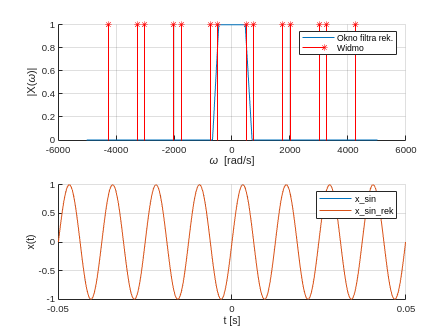

s = 4/5; 
ws = s*wg;
x_sin = sin(ws*t);

X_FT_sin_org = fourier(x_sin);
X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
BND_t = [-10/fp,10/fp];

%t_SMP = [BND_t(1):1/(10*fp):BND_t(2)];
BND_w = [-4*wp,4*wp];
w_SMP = BND_w(1):wp/10:BND_w(2);

figure;

subplot(2,1,1); 
hold on; 
grid on;

fplot(FILT_FT, BND_w); %okno filtru rek.ez
%ezplot(X_FT_sin,BND_w)
v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
n = find(abs(v_num) == Inf);

stem(w_SMP(n),sign(v_num(n)),'r*');
xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
legend('Okno filtra rek.','Widmo');

subplot(2,1,2); hold on; grid on;
fplot(x_sin, BND_t);

% syg. próbkowany
fplot(x_sin_rek, BND_t) % syg. odtworzony
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_rek');
hold off

## Zadanie 2

W drugim zadaniu przedstawiono jak wyglądają punkty danych, które zbieramy próbkując sygnał sinusoidalny z częstotliwością $f_p$. Wyniki przedstawiono na wykresie poniżej:

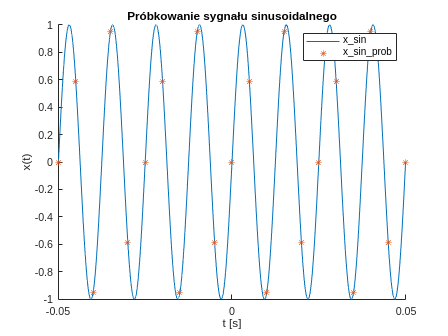

tt = BND_t(1):1/fp:BND_t(2);
figure();
hold on;
title("Próbkowanie sygnału sinusoidalnego");
fplot(x_sin, BND_t)
plot(tt,sin(ws*tt),"*")
xlabel('t [s]'); ylabel('x(t)')
legend('x\_sin','x\_sin\_prob');
hold off

## Zadanie 3

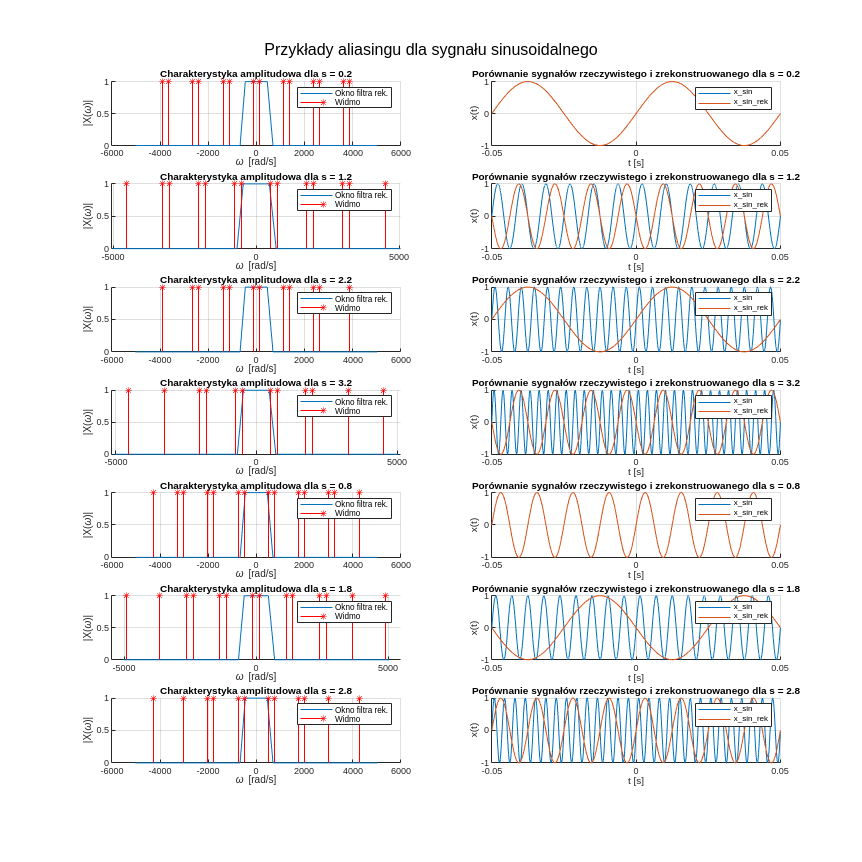

s_val = [1/5, 6/5, 11/5, 16/5, 4/5, 9/5, 14/5];

figure(Position=[100, 100, 1200, 1200])
sgtitle("Przykłady aliasingu dla sygnału sinusoidalnego")
for s = 1:length(s_val)
    ws = s_val(s)*wg;
    x_sin = sin(ws*t);
    
    X_FT_sin_org = fourier(x_sin);
    X_FT_sin = X_FT_sin_org + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

    FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
    x_sin_rek = ifourier(X_FT_sin*FILT_FT); % odwr. tarnsf. Fouriera
    BND_t = [-10/fp,10/fp];

    subplot(length(s_val),2,2*s-1); 
    hold on; 
    grid on;
    
    fplot(FILT_FT, BND_w); %okno filtru rek.ez + ... % oryginal widma
   symsum((subs(X_FT_sin_org, w, w - K*wp ) + ... % 3 aliasy lewe
   subs(X_FT_sin_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe
    % % %ezplot(X_FT_sin,BND_w)
    v_num = abs(double(subs(X_FT_sin, w, w_SMP)));
    n = find(abs(v_num) == Inf);
    
    stem(w_SMP(n),sign(v_num(n)),'r*');
    xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
    legend('Okno filtra rek.','Widmo');
    title_graph = "Charakterystyka amplitudowa dla s = " + num2str(s_val(s));
    title(title_graph)
    
    subplot(length(s_val),2,2*s); hold on; grid on;
    fplot(x_sin, BND_t);
    
    % syg. próbkowany
    fplot(x_sin_rek, BND_t) % syg. odtworzony
    title_graph = "Porównanie sygnałów rzeczywistego i zrekonstruowanego dla s = " + num2str(s_val(s));
    title(title_graph)
    xlabel('t [s]'); ylabel('x(t)')
    legend('x\_sin','x\_sin\_rek');
end

Na podstawie analizy powyższych wykresów dostajemy empiryczne potwierdzzenie poprawności twierdzenia Nyquista-Shannona. Dla sygnałów o częstotliwości próbkowania większej niż $f_g$, zachodzi zjawisko aliasingu i sygnał jest zniekształcony. Zrekonstruowaną dla aliasingu częstotliwość można natomiast wyznaczyć za pomocą wzoru:


$$f_r =| f_s - k  \cdot f_p|, \ dla  \ k   \in \mathbb{Z}$$


Zatem, aby uzyskać sygnał stały przy pomocy aliasingu należy spróbkować sygnał o częstotliwośći $k \cdot f_p$.

## Zadanie 4

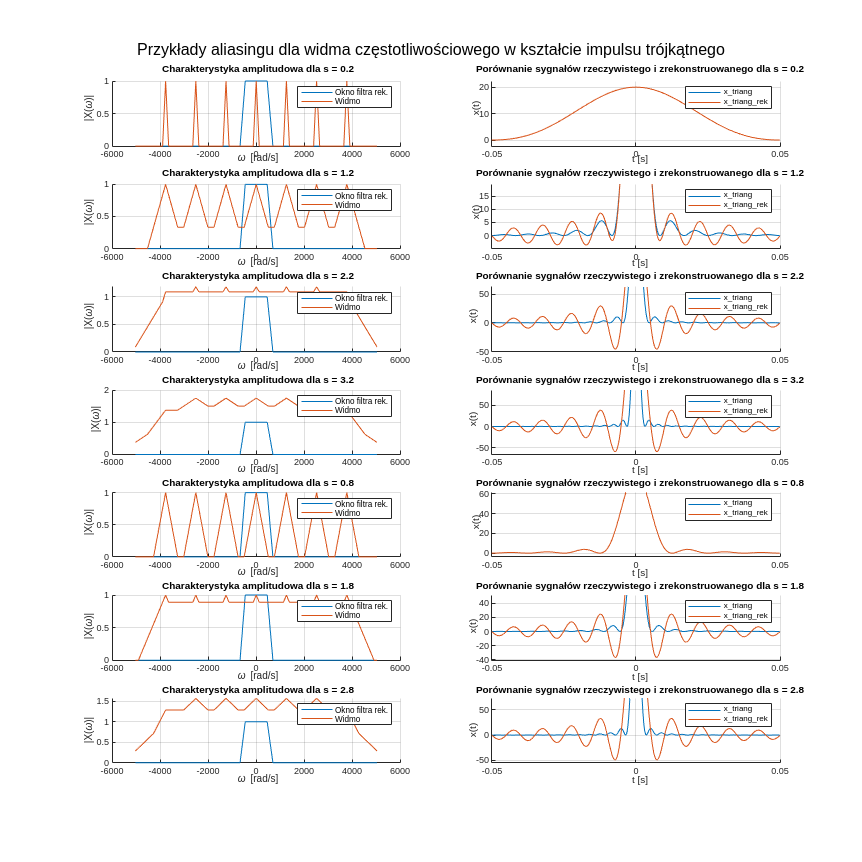

s_val = [1/5, 6/5, 11/5, 16/5, 4/5, 9/5, 14/5];
t_vals = linspace(BND_t(1), BND_t(2), 1000); % High resolution for smooth curves


figure(Position=[100, 100, 1200, 1200])
sgtitle("Przykłady aliasingu dla widma częstotliwościowego w kształcie impulsu trójkątnego")
for s = 1:length(s_val)
    ws = s_val(s)*wg;

    
    
    % Widmo częstotliwościowe
    X_FT_triang_org = triangularPulse(-ws,ws,w);

    x_triang = ifourier(X_FT_triang_org);
    X_FT_triang = X_FT_triang_org + ... % oryginal widma
        symsum((subs(X_FT_triang_org, w, w - K*wp ) + ... % 3 aliasy lewe
        subs(X_FT_triang_org, w, w + K*wp)), K , 1, 3); % 3 aliasy prawe

    % Filtr rekonstruujący
    FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy

    % Sygnał odtworzony
    x_triang_rek = ifourier(X_FT_triang*FILT_FT); % odwr. tarnsf. Fouriera
    BND_t = [-10/fp,10/(fp)];

    %%%%%%%%%%%%%%%%%%%%%%%%%
    % Wykresy
    %%%%%%%%%%%%%%%%%%%%%%%%% 
    %Dziedzina częstotliwości
    subplot(length(s_val),2,2*s-1); 
    
    hold on; 
    grid on;
    
    fplot(FILT_FT, BND_w); %okno filtru rek.ez
    fplot(X_FT_triang,BND_w)

    xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
    legend('Okno filtra rek.','Widmo');
    title_graph = "Charakterystyka amplitudowa dla s = " + num2str(s_val(s));
    title(title_graph)
    hold off

    % Dziedzina czasu
    subplot(length(s_val),2,2*s); 
    hold on; 
    grid on

    ezplot(x_triang, BND_t);% syg. próbkowany
    ezplot(x_triang_rek, BND_t) % syg. odtworzony

    xlabel('t [s]'); ylabel('x(t)')
    legend('x\_triang','x\_triang\_rek');
    title_graph = "Porównanie sygnałów rzeczywistego i zrekonstruowanego dla s = " + num2str(s_val(s));
    title(title_graph)
    hold off 
end

W tym zadaniu spotykamy się z aliasingiem, gdie aliasing prowadzi do widocznych zniekształceń w dziedzinie częstotliwości, Poprzez nakładanie się sygnału na siebie przebirg trójkątny w dziedzinie pulsacji zmienai się w sygnał, znacznie różniący się od pierwotnego. W wyniku tego odwzorowanie sygnału nie jest  równoznaczne jego rzeczywistemu przebiegowi.

## Zadanie 5

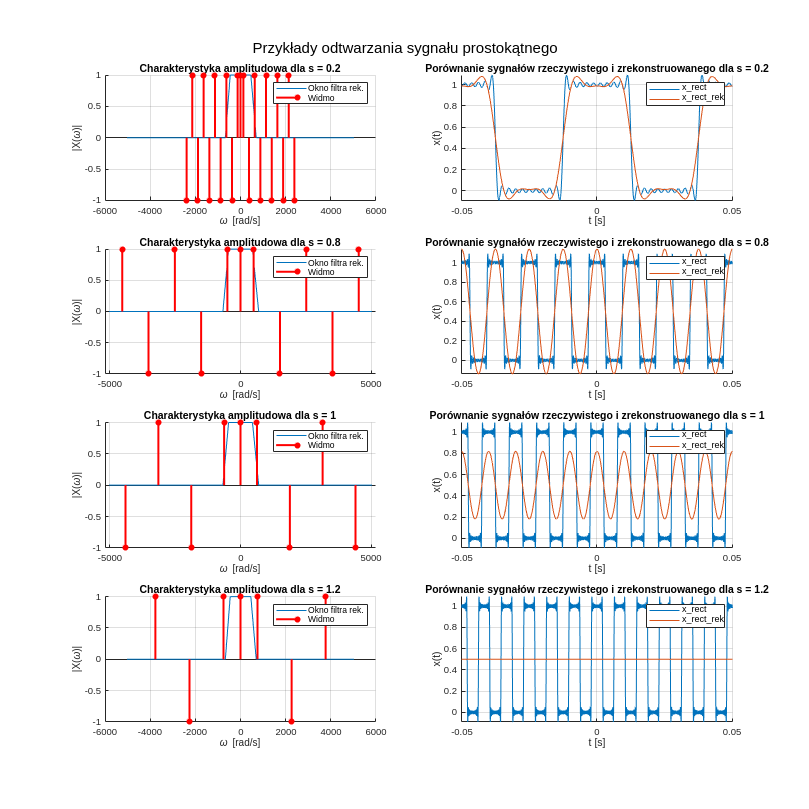

s_val = [1/5, 4/5, 1, 6/5];
NT = 20;
ind = -NT:NT;
X = zeros([1, 2*NT+1]);

figure(Position=[100 100 1200 1200]);
sgtitle("Przykłady odtwarzania sygnału prostokątnego");
for s = 1:length(s_val)
    
    ws = s_val(s)*wg;
    x = rectangularPulse(-pi/(2*ws),pi/(2*ws),t);
    % Generowanie współczynników
    for nx = ind
        Xn = ws/(2*pi)*int(x*exp(-1i*ws*nx*t),t,BND_t);
        X(nx + NT + 1) = Xn;
    end
    

    x_rect = sum(arrayfun(@(n) X(n+NT+1)*exp(1i*n* ws*t), ind));
    X_FT_rect_org = 2*pi* sum(arrayfun(@(n)  X(n + NT + 1)*dirac(w - (n * ws)), ind));
    
    FILT_FT = rectangularPulse(-wg,wg,w); % filtr rekonstruuj¡cy
    x_rect_rek = ifourier(X_FT_rect_org*FILT_FT); % odwr. tarnsf. Fouriera
    BND_t = [-10/fp,10/fp];


    %%%%%%%%%%%%%%%%%%%%%%%%%
    % Wykresy
    %%%%%%%%%%%%%%%%%%%%%%%%% 
    %Dziedzina częstotliwości
    subplot(length(s_val),2,2*s-1); hold on; grid on;
    
    fplot(FILT_FT, BND_w); %okno filtru rek.ez 

    % Sygnał jest parzysty, więc tylko część rzeczywista
    v_num = subs(real(X_FT_rect_org), w, w_SMP);
    n = find(abs(v_num) == Inf);
    nx = find(abs(X) ~= 0);
    stem(w_SMP(n),sign(v_num(n)),'r*', 'LineWidth', 2);


    xlabel('\omega [rad/s]'); ylabel('|X(\omega)|')
    legend('Okno filtra rek.','Widmo');
    title_graph = "Charakterystyka amplitudowa dla s = " + num2str(s_val(s));
    title(title_graph)
    hold off 
    

    %Dziedzina czasu
    subplot(length(s_val),2,2*s); hold on; grid on;
    
    fplot(x_rect, BND_t);% syg. próbkowany
    fplot(x_rect_rek, BND_t) % syg. odtworzony
    
    xlabel('t [s]'); ylabel('x(t)')
    legend('x\_rect','x\_rect\_rek');
    title_graph = "Porównanie sygnałów rzeczywistego i zrekonstruowanego dla s = " + num2str(s_val(s));
    title(title_graph)

    hold off
end

Na podstawie wykresów poniżej można zauważyć, żę im niższa częstotliwość podstawowa sygnału, tym lepiej jest on odwzorowany. Puls prostokątny jest tutaj reprezentowany poprzez aproksymację szeregiem Fouriera dla $n \in (-20,20)$, za częstotliwość podstawową przyjmowano $\omega_s$, dlatego dla większego parametru s, sygnał nie mógł być już odpowiednio skonstruowany, co przedstawiono na wykresach. Można zauważyć coraz to gorsze odwsorowanie dla rosnącego parametru s. Dlatego, aby uzyskać jak najlepsze odwzorowanie sygnału prostokątnego o danej częstotliwości, to najlepiej próbkować go znacznie wyższą częstotliwością.

# Wnioski

Na laboratorium zapoznano się z podstawami próbkowania sygnałów i zjawiskiem aliasingu. W przetwarzaniu cyfrowym sygnałów jest to element, na który trzeba szczególnie uważać, aby wyniki analiz nie okazały się nie zgodne z prawdą i pozbawione żadnego sensu. Trzeba zwracać na to zawsze szczegółną uwagę i stosować twierdzenie Nyquista-Shannona. Zapoznanie się jednak z ryzykiem jakie może to nieść i przeanalizowanie tego na przykładach skutecznie ilustruje problem i pomaga unikać go oraz uczy jak sobie poradzić z nim w przyszłości.